# Using wavelet toolbox for denoising

## Introduction

The signals in the real word are always changing slowly or oscillating suddenly with transients. Similarly, images also have smooth regions interrupted by edges or abrupt changes in contrast.

The reason why we use wavelet is that although Fourier transform (which is made up of the sum of sine waves) is powerful for analyzing data, it cannot represent the sudden change efficiently.

In this case, we need wavelets which is a new function for us to deal with the abrupt changes for 1-D signals or 2-D images.

## Denoising 1-D signal

In this case, we will use Discrete Wavelet Transform, different with continous transform, it is normally used for denoising and compressing.

In this part, I also refered to the online tutorial from MathWorks.

### Load the signal

To implement this, we firstly using a file containing a noisy signal.

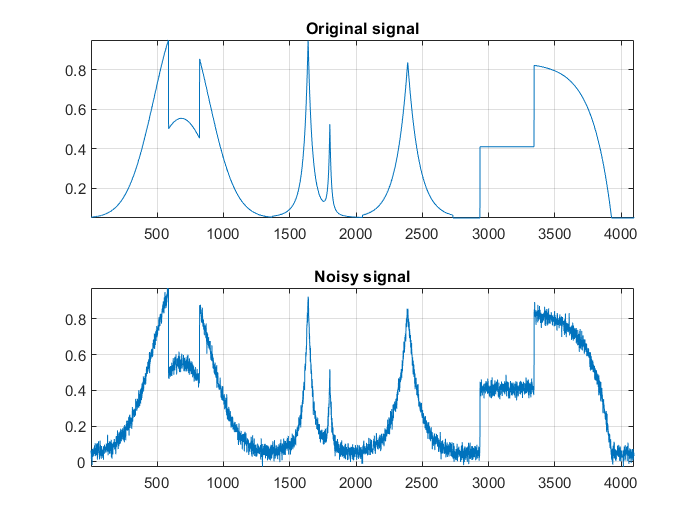

load noisysig.mat
figure; 
subplot(2,1,1); 
plot(f0);
grid on; 
title('Original signal'); 
axis tight; 
subplot(2,1,2); 
plot(f); 
title('Noisy signal'); 
axis tight; 
grid on;

### Perform multilevel wavelet decomposition 

Then we need to perform a multilevel wavelet decomposition.

It is implemented by separating the noisy signal using a high pass and low pass filter respectively with several levels.

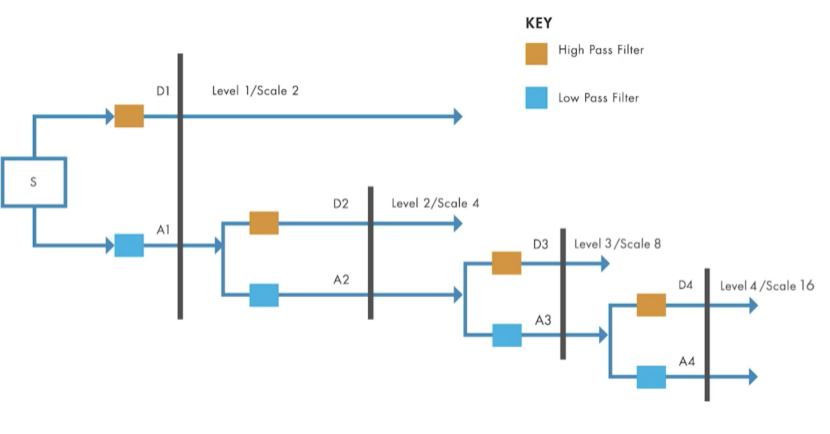

In this project, I will divide the noisy signal into four levels.

Besides, because there are different types of wavelet signals, I will choose the "sym6" wavelet.

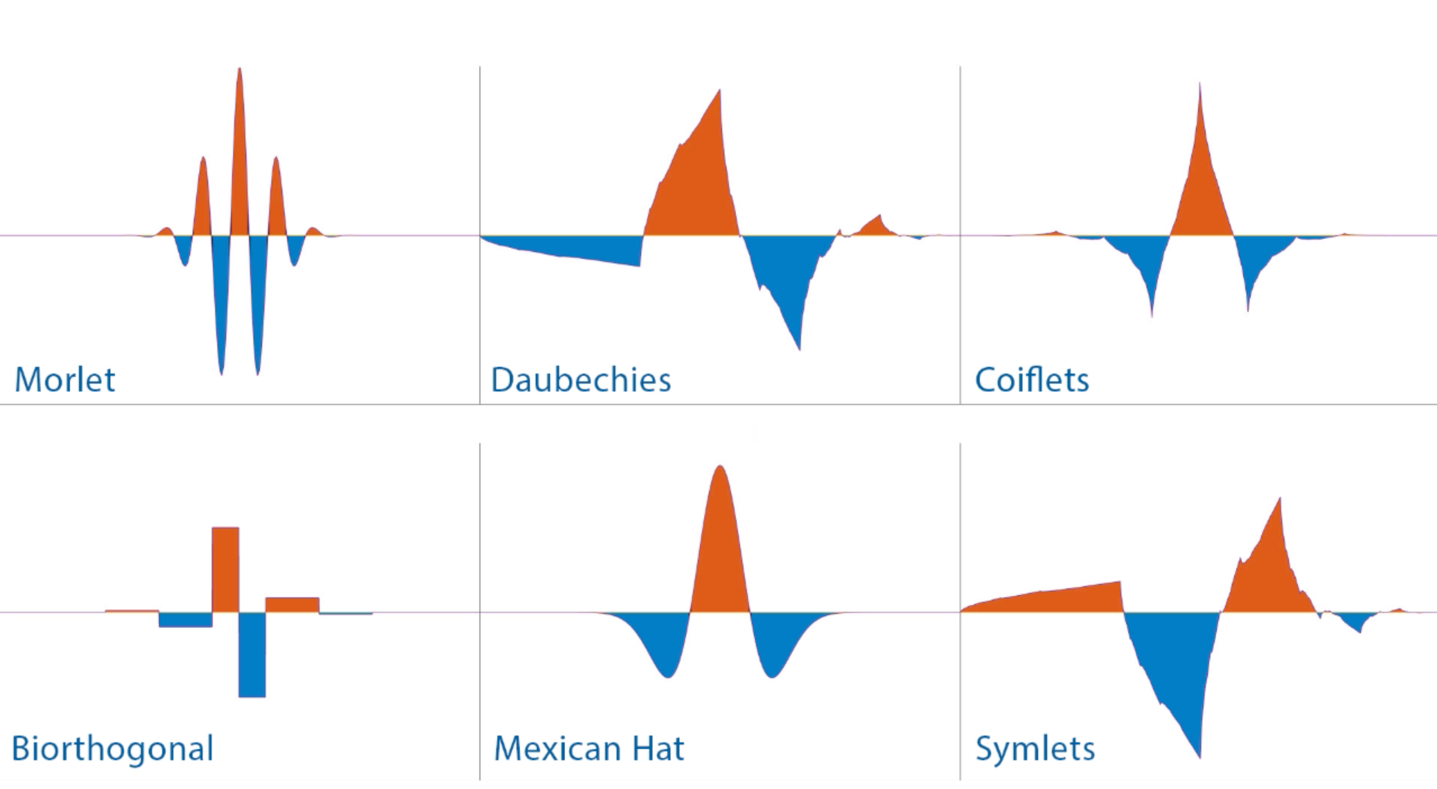

Because MATLAB has already provided a useful function called wavedec() in the wavelet toolbox, we could then using it.

dwtmode('per','nodisplay');

num_of_level = 4;

wavelet_name = 'sym6'

wavelet_name = 'sym6'

[C, L] = wavedec(f,num_of_level,wavelet_name);
depth = detcoef(C,L,'cells');
length(depth{1})

ans = 2048

length(depth{2})

ans = 1024

length(depth{3})

ans = 512

length(depth{4})

ans = 256

We could find that the length of each depth is decreasing, it is because we seperate the signal high pass and low pass filter.

## Denoising 1-D signal

Then we could apply wavelet denoising using wden() function which is provided in the wavelet toolbox in MATLAB.

But before that, we first need to know how and why we need to set up threshold.

#### Threshold

As we know that, most of the noise is contained in the high frequency level. The high pass part is caused by the sudden change of the signal. However, because sometimes it contains some useful information, we will try to save those information during denosing. In this case, one way to do this is by scaling the detail coefficients by a threshold.

There are several techniques to compute the threshold, and I will use "Sure Shrink" in this case.

Also, there are two methods to apply the threshold (soft and hard). The main difference between them is how to deal with the coefficients that are greater in magnitude than the threshold. And I will use hard threshold here.

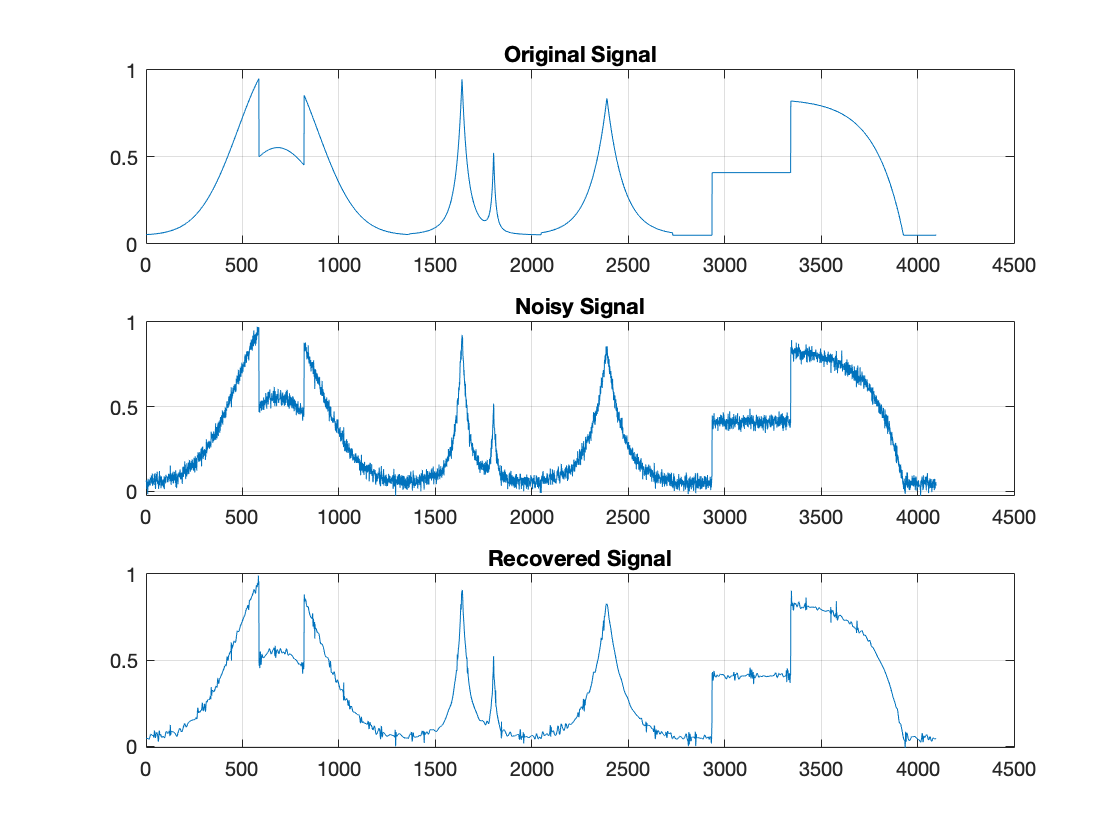

fd = wden(f,'rigrsure','h','sln',num_of_level,wavelet_name);
% "f" is the noisy signal
% "rigrsure" specifies the thresholding technique. And I used Sure Shrink.
% "h" means hard thresholding
% "sln" shows that threshold rescaling using a single estimate of noise based on first-level coefficients
% "num_of_level" is the number of levels used for decomposition
% "wavelet_name" is the type of wavelet, we used "sym6" here

figure; 
subplot(3,1,1);
plot(f0); 

grid on;
title('Original Signal');
subplot(3,1,2); 
plot(f);
 
grid on;
title('Noisy Signal');
subplot(3,1,3)
plot(fd); 
 
grid on;
title('Recovered Signal');

We could also calculate the signal-to-noise ratio in dB in order to show the effect in an accurate way. The SNR increased by 6dB after we denoising, means the quality of the image increased.

sprintf('Noisy Signal SNR:  %0.2f dB',-20*log10(norm(abs(f0-f))/norm(f0)))

ans = 'Noisy Signal SNR:  24.44 dB'

sprintf('Denoised Signal SNR:  %0.2f dB',-20*log10(norm(abs(f0-fd))/norm(f0)))

ans = 'Denoised Signal SNR:  30.73 dB'

## Comparing with other wavelet methods for denoising

ans = 'Wavelet Denoising SNR:  30.73 dB'

ans = 'Savitzky Golay SNR:  29.01 dB'

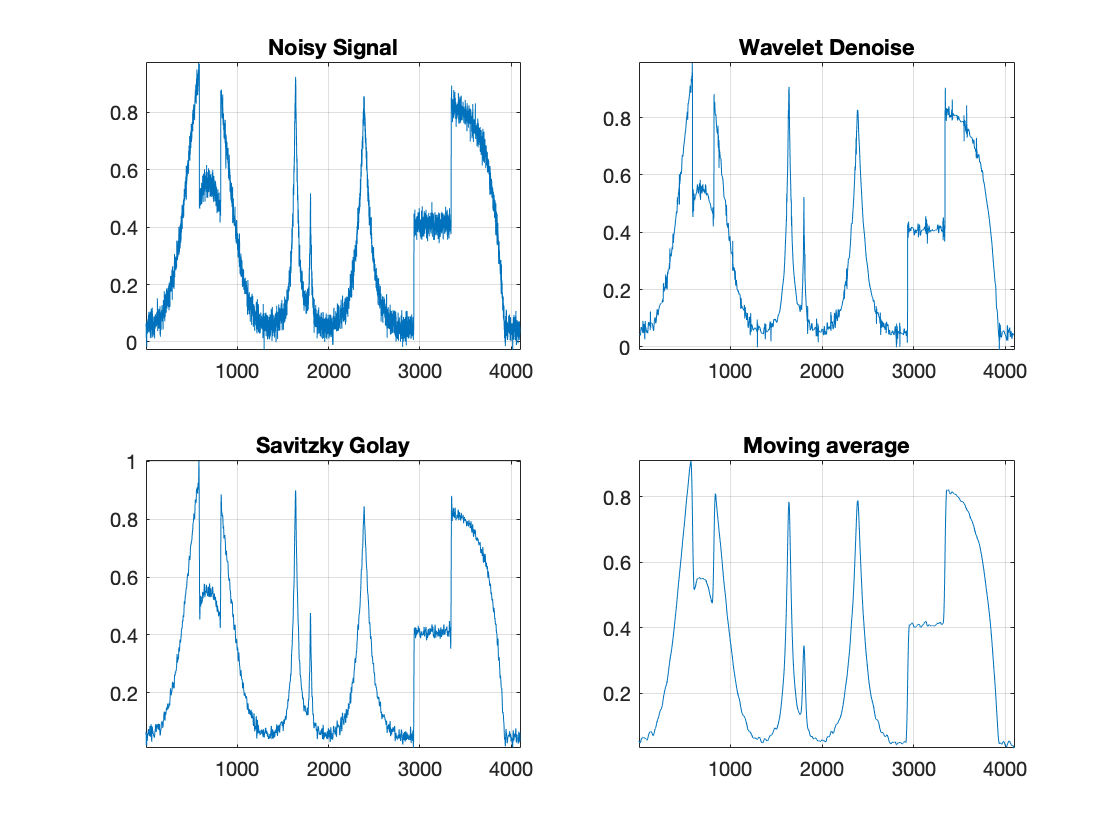

ans = 'Moving Average SNR:  26.14 dB'

figure; 
subplot(2,2,1); 
plot(f);
axis tight; 
grid on;
title('Noisy Signal');

subplot(2,2,2)
plot(fd); 
axis tight;
grid on;
title('Wavelet Denoise');
sprintf('Wavelet Denoising SNR:  %0.2f dB',-20*log10(norm(abs(f0-fd))/norm(f0)))

subplot(2,2,3)
sgolay = sgolayfilt(f,31,101);
plot(sgolay); 
axis tight; 
grid on;
title('Savitzky Golay');
sprintf('Savitzky Golay SNR:  %0.2f dB',-20*log10(norm(abs(f0-fsg))/norm(f0)))

subplot(2,2,4)
movavg = 1/20*ones(20,1);
fmv = filtfilt(movavg,1,f);
plot(fmv); 
axis tight; 
grid on;
title('Moving average');
sprintf('Moving Average SNR:  %0.2f dB',-20*log10(norm(abs(f0-fmv))/norm(f0)))

After comparing the SNR to noise ratio, we could find the wavelet denoising has a lager SNR, which means the ratio noise is smaller than signal. We could say it has a better denoising result.

## Denoising 2-D image

Similarly, we will also use the knowledge of wavelet for denoising the image. But the difference is that, an image could be considered as a 2-D matrix. The steps will be shown below in detail.

### Load an original image with its noisy image.

clear all
clc
myImage = imread('race.tif') ;
myImage = double(myImage) ;

myImageN1 = imread('noise1.tif') ;
myImageN1 = double(myImageN1) ;

### 2-D wavelet decomposition

Then, we will use wavedec2() function with coiflet (coif2) wavelet filter to divided the image in two levels. Different with that in 1-D signal denoising, I used 'sym6' wavelet filter with 4 levels for decpmposition.

[c,l] = wavedec2(myImageN1,2,'coif2');

Set up the scale vector (n) and threshold vector (p)

n  = [2,1];
p = [10,23];

Dealing with the threshold three times, first for horizontal, then of vertical and finally for diagonal to make the result accruate. And I used soft method.

nc = wthcoef2('h',c,l,n,p,'s');
X1 = waverec2(nc,l,'coif2');
% image(X1)
mc = wthcoef2('v',nc,l,n,p,'s');
X2 = waverec2(mc,l,'coif2');
% image(X2)
tc = wthcoef2('d',mc,l,n,p,'s');
X3 = waverec2(tc,l,'coif2');
% image(X3)

Plot the denoising signal, compared it with the original one and noisy one.

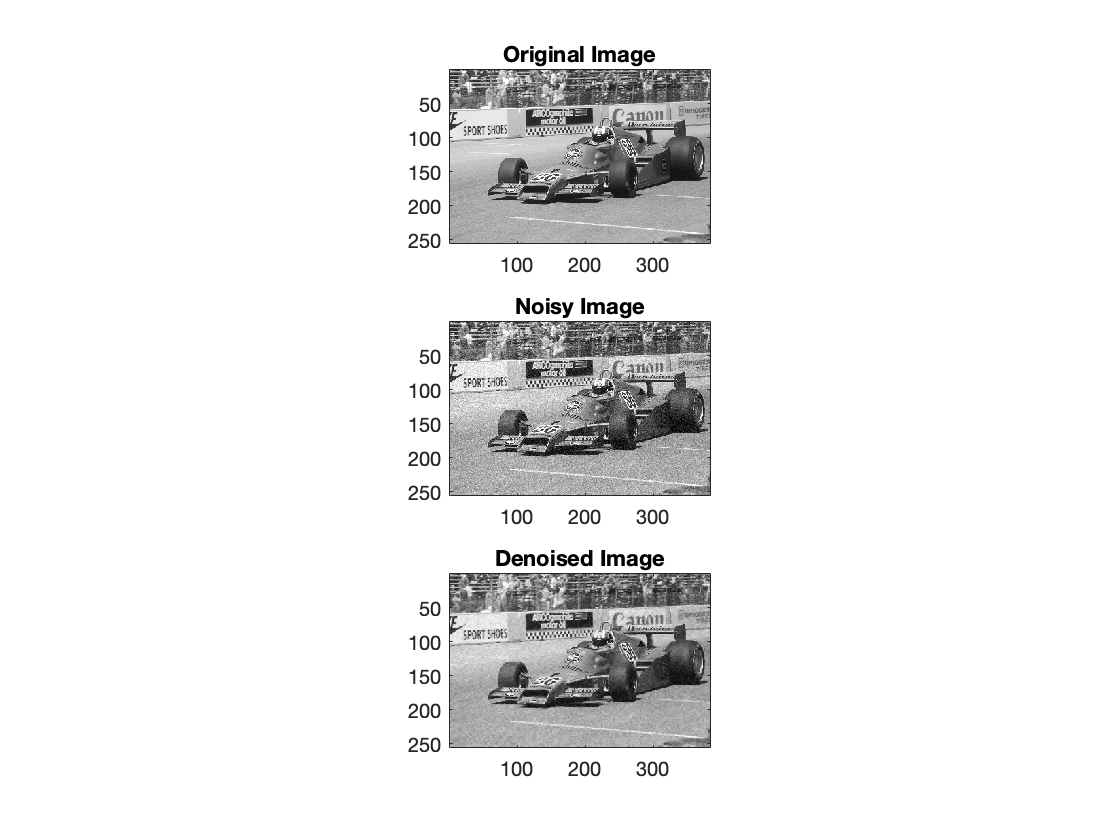

figure; 
subplot(3,1,1);
image(myImage)
colormap(gray(256))
axis('image')
title('Original Image')
hold on

subplot(3,1,2);
image(myImageN1)
colormap(gray(256))
axis('image')
title('Noisy Image')
hold on

subplot(3,1,3);
image(X3)
colormap(gray(256))
axis('image')
title('Denoised Image')

### Using SNR to show the signal-to-noise ratio before and after denoising.

sprintf('Noisy Signal SNR:  %0.2f dB',-20*log10(norm(abs(myImage-myImageN1))/norm(myImage)))

ans = 'Noisy Signal SNR:  20.35 dB'

sprintf('Recovered Signal SNR:  %0.2f dB',-20*log10(norm(abs(myImage-X3))/norm(myImage)))

ans = 'Recovered Signal SNR:  23.17 dB'

We could find the SNR value increased by 3dB after denoising.

## Reference

Kirthi Devleker, *MathWorks, Understanding Wavelets, *Retired from:

https://au.mathworks.com/videos/understanding-wavelets-part-3-an-example-application-of-the-discrete-wavelet-transform-121284.html?s_tid=vid_pers_recs